# Twin simulation

To simultate the digital twin from the data retrieved using ROS2 it is first necessary to subsample the data in order to have a reasonable computing time, then some elaboration on the data is performed and lastly a simulation of the drone track is done and recorded.

The following livescript will be divided into three parts: the first part will contain the import for the track data, the second part will perform some elaboration on the data, visualizing the starting point of the track in both 2D and 3D and then the last part concers the simulation of the track, realizing a "digital twin".

### Import Flight Track Data

Import the already subsampled simulated flight track data. The .csv file contains the latitudes, longitudes, and altitudes of the drone mission, retrieved using ROS2.

T = readtable("subsampled.csv");
lat= T.lat';
lon = T.lon';
alt = T.alt';

### Visualization of starting point 

#### View of  the starting Point in 2D

For a 2-D perspective of the region, `geoaxes` and `geoplot` are used to plot the location the starting point of the Drone mission, which is retrieved as the first point in the .csv file.

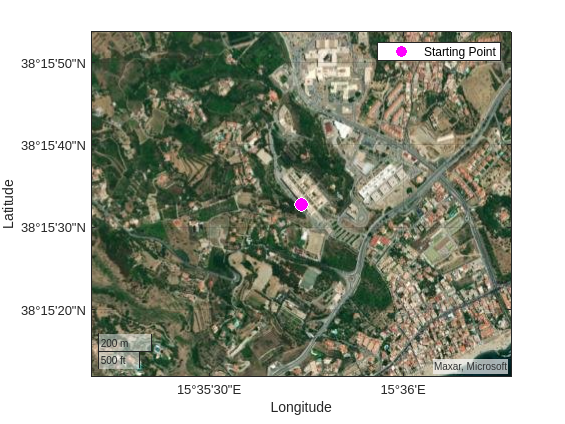

splat = lat(1);
splon = lon(1);
spalt = alt(1);

figure
geoaxes("Basemap","satellite","ZoomLevel",15)
hold on
geoplot(splat,splon,"ow","MarkerSize",10,"MarkerFaceColor","magenta", "DisplayName","Starting Point")
legend

### Creation of Geographic Axes and Geographic Globe in Same Figure

In order to view 2-D and 3-D map display in the same image geographic axes and a geographic globe are created. From this starting point the view will be subsequently adjusted to view only the starting poin and the track of the drone.

figpos = [1000 500 800 400];
uif = uifigure("Position",figpos);
ug = uigridlayout(uif,[1,2]);
p1 = uipanel(ug);
p2 = uipanel(ug);
gx = geoaxes(p1,"Basemap","satellite"); 
gg = geoglobe(p2); 
gx.InnerPosition = gx.OuterPosition;
gg.Position = [0 0 1 1];

#### View of the Starting Point in 2D

View of the starting point from 200 meters above the terrain. The view is centered to the starting point and by using the *heightToZoomLevel *function defined at the end of the script the height is converted to the correct zoom level.

heightAboveTerrain = 200;
gx.MapCenter = [splat, splon];
zoomLevel = heightToZoomLevel(heightAboveTerrain, splat);
gx.ZoomLevel = zoomLevel;

#### View of the Starting Point in 3D

Same view as before, but this time it is in 3D. The *campos() *function requires the ellipsoidal height and not the orthometric one, then the height must be converted to ellipsoidal in order to draw the 3D view of the starting point.

N = egm96geoid(splat, splon);
spalt = 500.00 + N;
ellipsoidalHeight = spalt + heightAboveTerrain;
campos(gg,splat,splon,ellipsoidalHeight)
drawnow


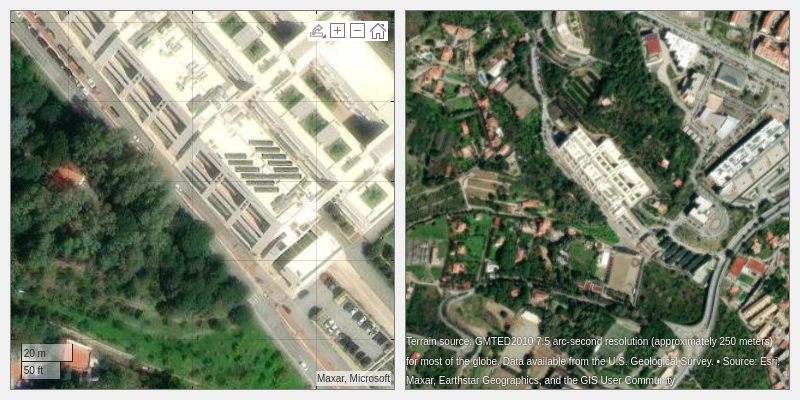

### Calculation of Flight Headings

The drone heading at each point are computed using the `azimuth` function.

wgs84 = wgs84Ellipsoid;
theading = azimuth(lat(1:end-1),lon(1:end-1),lat(2:end),lon(2:end),wgs84);
theading = [theading(1);theading(:)];


### 3-D Distances of the Mission

Computation of the cumulative distance covered by the drone during the mission, since it needs to take into account the changes in altitude, the ecef0ffset function is used to compute point-to-point offsets, expressed in meters.

N = egm96geoid(lat,lon);
h = alt + N;
lat1 = lat(1:end-1);
lat2 = lat(2:end);
lon1 = lon(1:end-1);
lon2 = lon(2:end);
h1 = h(1:end-1);
h2 = h(2:end);
[dx,dy,dz] = ecefOffset(wgs84,lat1,lon1,h1,lat2,lon2,h2);
distanceIncrementIn3D = hypot(hypot(dx, dy), dz);
cumulativeDistanceIn3D = cumsum(distanceIncrementIn3D);
totalDistanceIn3D = sum(distanceIncrementIn3D);
fprintf("During the entire mission the drone path is long %.2f meters.\n",totalDistanceIn3D)

During the entire mission the drone path is long 11320.19 meters.


In order to plot thesimulation the cumulative distance is assigned to a variable

dist = [0 cumulativeDistanceIn3D];

### Plot the flight path

Plot the simulated path from the starting point to the arrival point, and visualize all the region of space covered. The zoom is automatically updated in order to view all the path.

geoplot3(gg,lat,lon,alt,"c","LineWidth",2,"HeightReference","geoid")
ptrack = geoplot(gx,lat,lon,"c","LineWidth",2);

[clat,clon,cheight] = campos(gg);
gx.MapCenter = [clat,clon];
gx.ZoomLevel = heightToZoomLevel(cheight, clat);
drawnow


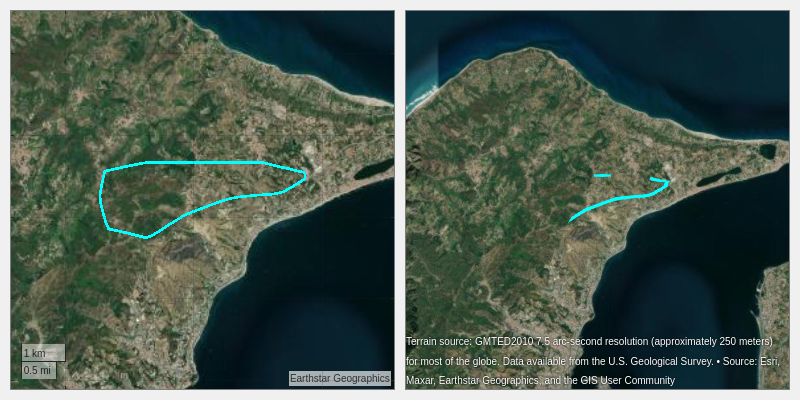

### Setting the initial view for the simulation

Visualize the flight path from the start position, to get a better perspective, the camera height is set to 75 meters over the altitude of the starting point. 


campos(gg,lat(1),lon(1))
camheight(gg,alt(1) + 300)
campitch(gg,-90)
camheading(gg,theading(3))

Settings for the markers about start, current and end location of the Drone and to print latitude, longitude and altitude of the Drone. The distance covered from the starting point is also displayed.

hold(gx,"on")
marker = geoplot(gx,lat(1),lon(1),"ow","MarkerSize",10,"MarkerFaceColor","k");
mstart = geoplot(gx,lat(1),lon(1),"ow","MarkerSize",10,"MarkerFaceColor","magenta");
mend = geoplot(gx,lat(end),lon(end),"ow","MarkerSize",10,"MarkerFaceColor","blue");

marker.DisplayName = "Current Location";
mstart.DisplayName = "Start Location";
mend.DisplayName = "End Location";
ptrack.DisplayName = "Drone Track";
legend(gx)
gx.Basemap = "topographic";
dt = datatip(ptrack,"DataIndex",1,"Location","southeast");
dtrow = dataTipTextRow("Distance",tdist);
dtrow(end+1) = dataTipTextRow("Altitude",alt);
dtrow(end+1) = dataTipTextRow("Heading",theading);
ptrack.DataTipTemplate.DataTipRows(end+1:end+3) = dtrow;



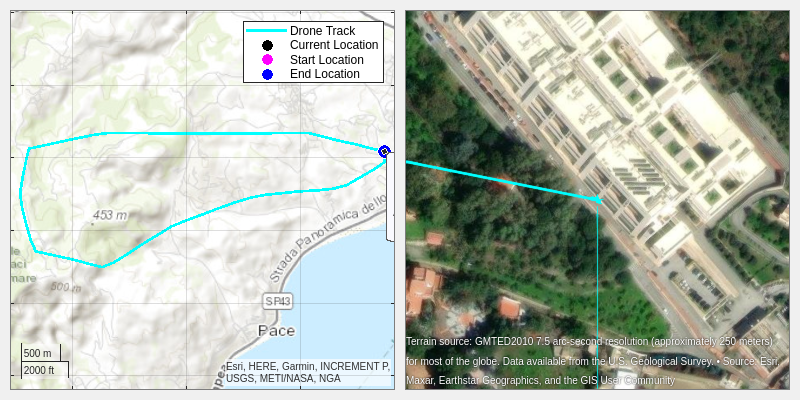

## Simulation of the Digital Twin

A simulation of the Digital Twin from the data retrieved from ROS 2 is run, the UI will be the same as before, on the left will be displayed the track of the drone with information about coordinates and distance covered, while on the right will be displayed a 3D render of what the camera should view. 

pitch = -2.7689;
campitch(gg,pitch)

for k = 2:(length(lat)-1)

    campos(gg,lat(k),lon(k))
    camheight(gg,alt(k)+100)
    camheading(gg,theading(k))
    
    set(marker,"LatitudeData",lat(k),"LongitudeData",lon(k));
    dt.DataIndex = k;
    
    drawnow
    pause(.05)
end

campos(gg,lat(end),lon(end),alt(end)+100)
dt.DataIndex = length(lat);

Function to convert height from wgs84 to zoom level.

function zoomLevel = heightToZoomLevel(height, lat)
    earthCircumference = 2 * pi * 6378137;
    zoomLevel = log2((earthCircumference *cosd(lat)) / height) + 1;
    zoomLevel = max(0, zoomLevel);
    zoomLevel = min(19, zoomLevel);
end